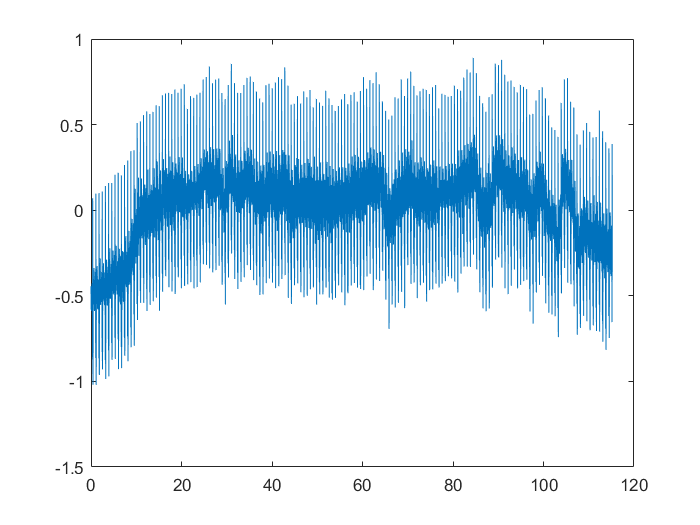

% Preprocessing ECG signal
% Sina Dabiri, 2021
clear

[sig, Fs, tm] = rdsamp('ptbdb/patient001/s0014lre', 1);
data = sig';
plot(tm, sig);

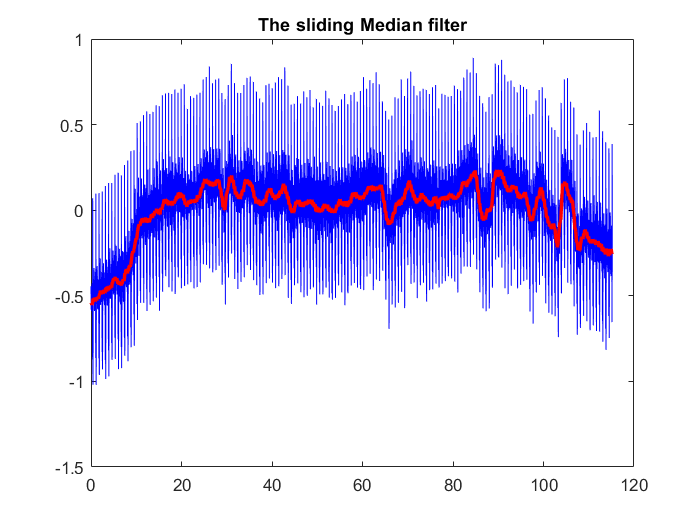

hold on
plot(tm, sig, 'b-');
% 'md' with wlen=0.2 sec
wlen = round(0.6*Fs);
b_md = BaseLine1(data, wlen,'md');

plot(tm, b_md, 'r-', 'LineWidth',2);
title("The sliding Median filter");
hold off

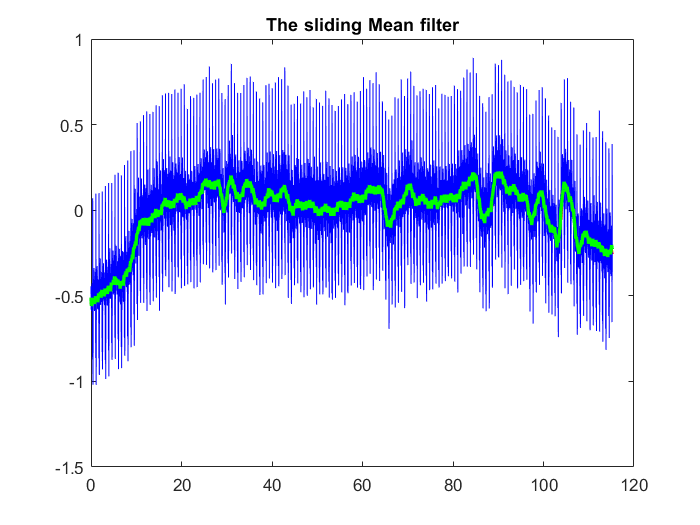

hold on
plot(tm, sig, 'b-');
% 'ma' with wlen=0.3 sec
wlen = round(0.8*Fs);
b_mn = BaseLine1(data, wlen,'mn');

plot(tm, b_mn, 'g-', 'LineWidth',2);
title("The sliding Mean filter");
hold off

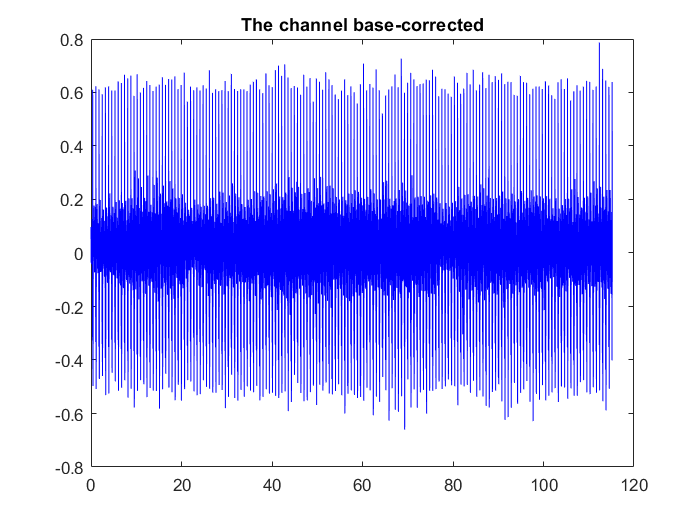

% Powerline noise cancellation

data_base_cor = data - b_md;
plot(tm, data_base_cor, 'b-');
title("The channel base-corrected");

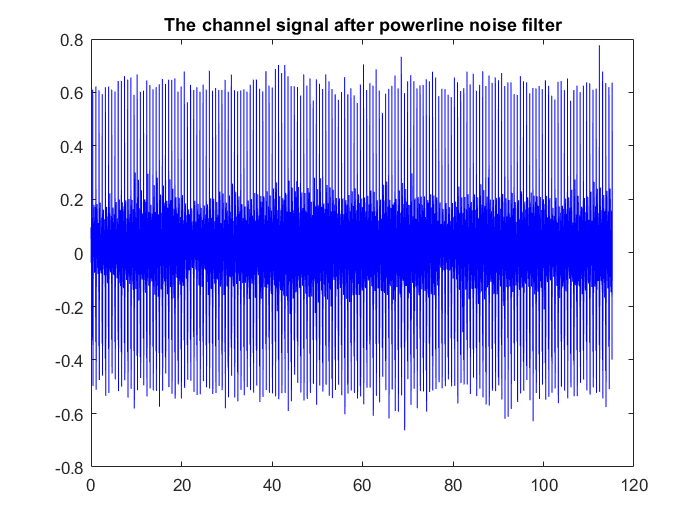

% notch filter design

fs = Fs; % sampling frequency (Hz)
f0 = 60; % powerline frequency (50Hz or 60Hz, depending on the country that the data has been recorded in)
Q = 40; % Q-factor (quality factor) of the notch filter. a parameter that controls the notch quality and is a compromise between transient response time and notch quality
Wo = f0/(fs/2); % powerline frequency normalized by the Nyquist frequency 
BW = Wo/Q; % normalized notch filter bandwidth
[b,a] = iirnotch(Wo,BW); % design the filter numerator and denominator
 
% looking at the frequency response
% fvtool(b, a)
x=  data_base_cor;
% filtering a 1-D signal x (apply it on each channel if the signal is multi-dimensional)
y = filter(b, a, x);
plot(tm, y, 'b-')
title("The channel signal after powerline noise filter");

% QT Interval Estimation:

% 1- Non-model method: Dr. Qiao wavelet method
%  https://github.com/cliffordlab/QTestimation.git
fs0 = num2str(fs);
QT_output = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Clifford and Dr. Sameni\QT_pipeline\QT_output.csv'

QT_output = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Clifford and Dr. Sameni\QT_pipeline\QT_output.csv'

QT_analysis(y, fs0, '1', '1', QT_output, 'a');

record =     0.0667    0.0962    0.0843    0.0777    0.0809    0.0717    0.0608    0.0594    0.0691    0.0683    0.0619    0.0548    0.0374    0.0336    0.0460    0.0482    0.0388    0.0366    0.0376    0.0250    0.0159    0.0168    0.0115    0.0249    0.0413    0.0379    0.0314    0.0225    0.0179    0.0212    0.0248    0.0278    0.0152    0.0054    0.0105    0.0035   -0.0098   -0.0317   -0.0364   -0.0090    0.0127    0.0124    0.0026   -0.0089   -0.0203   -0.0005    0.0243    0.0302    0.0245    0.0019


fs0 = 1000

nlead = 1

lead = 1

output = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Clifford and Dr. Sameni\QT_pipeline\QT_output.csv'

output_permission = 'a'

Error using csvread (line 29)
File name must be a character vector.

Error in QT_analysis (line 41)
data=csvread([record],1,0);